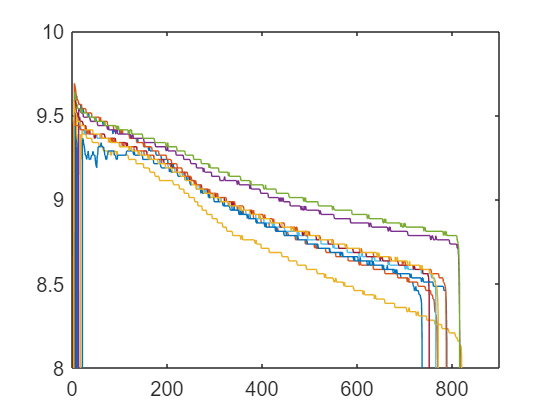

Req = (1/(13*(1/1.5)));


clear opts

opts = spreadsheetImportOptions("NumVariables", 2);


%%% TEST 1 %%%
% Specify sheet and range
opts.Sheet = "Test1(Clean)";
opts.DataRange = "A1:B545";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test1 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test1(Clean).xlsx", opts, "UseExcel", false);
Test1.Time=Test1.Time-165561;
Test1Current=Test1.Voltage/Req;


%%% TEST 2 %%%
% Specify sheet and range
opts.Sheet = "Test2";
opts.DataRange = "A1:B568";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test2 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test2(Clean).xlsx", opts, "UseExcel", false);
Test2.Time=Test2.Time-993852;
Test2Current=Test2.Voltage/Req;


%%% TEST 3 %%%
% Specify sheet and range
opts.Sheet = "Test3";
opts.DataRange = "A1:B571";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test3 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test3(Clean).xlsx", opts, "UseExcel", false);
Test3.Time=Test3.Time-1078485;
Test3Current=Test3.Voltage/Req;


%%% TEST 4 %%%
% Specify sheet and range
opts.Sheet = "Test4";
opts.DataRange = "A1:B567";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test4 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test4(Clean).xlsx", opts, "UseExcel", false);
Test4.Time=Test4.Time-1300548;
Test4Current=Test4.Voltage/Req;


%%% TEST 5 %%%
% Specify sheet and range
opts.Sheet = "Test5";
opts.DataRange = "A1:B642";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test5 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test5(Clean).xlsx", opts, "UseExcel", false);
Test5.Time=Test5.Time-18308;
Test5Current=Test5.Voltage/Req;


%%% TEST 6 %%%
% Specify sheet and range
opts.Sheet = "Test6";
opts.DataRange = "A1:B566";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test6 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test6(Clean).xlsx", opts, "UseExcel", false);
Test6.Time=Test6.Time-126343;
Test6Current=Test6.Voltage/Req;


%%% TEST 7 %%%
% Specify sheet and range
opts.Sheet = "Test7";
opts.DataRange = "A1:B555";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test7 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test7(Clean).xlsx", opts, "UseExcel", false);
Test7.Time=Test7.Time-176749;
Test7Current=Test7.Voltage/Req;


%%% TEST 8 %%%
% Specify sheet and range
opts.Sheet = "Test8";
opts.DataRange = "A1:B621";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test8 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test8(Clean).xlsx", opts, "UseExcel", false);
Test8.Time=Test8.Time-21658;
Test8Current=Test8.Voltage/Req;


%%% Test 9 %%%
% Specify sheet and range
opts.Sheet = "Test9";
opts.DataRange = "A2:B583";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test9 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test9(Clean).xlsx", opts, "UseExcel", false);
Test9.Time=Test9.Time-115782;
Test9Current=Test9.Voltage/Req;


%%% Test 10 %%%
% Specify sheet and range
opts.Sheet = "Test10";
opts.DataRange = "A1:B642";
% Specify column names and types
opts.VariableNames = ["Time", "Voltage"];
opts.VariableTypes = ["double", "double"];
% Import the data
Test10 = readtable("C:\Users\hoppeb\Documents\GitHub\BatteryModeling\FuseTestingData\11-11 0.1x4 Short\Test10(Clean).xlsx", opts, "UseExcel", false);
Test10.Time=Test10.Time-9391;
Test10Current=Test10.Voltage/Req;



plot(Test1.Time,Test1.Voltage,Test2.Time,Test2.Voltage,Test3.Time,Test3.Voltage, ... 
    Test4.Time,Test4.Voltage,Test5.Time,Test5.Voltage,Test6.Time,Test6.Voltage, ...
    Test7.Time,Test7.Voltage,Test8.Time,Test8.Voltage,Test9.Time,Test9.Voltage, ...
    Test10.Time,Test10.Voltage)
axis([0,900,8,10]);